# Taller 2 OCDR

# Consensus Protocol

# Gabriela María Castro Beltrán

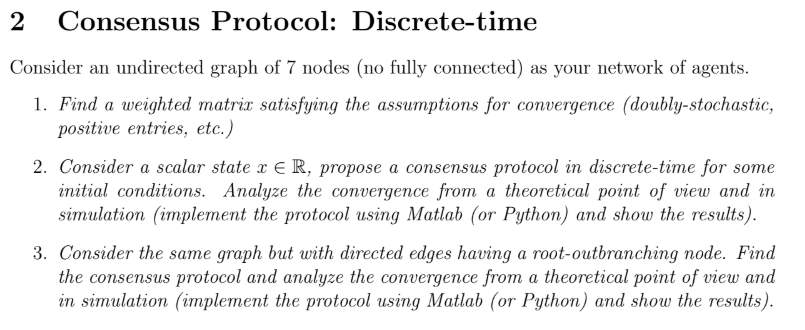

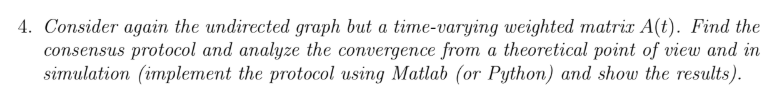

## El protocolo de consenso en tiempo discreto para un Grafo no dirigido

Se crea un gráfico aleatorio de 7 nodos, asegurando que sea conectado. Calcula la matriz de Laplaciana L del gráfico y luego genera una matriz W doblemente estocástica usando W=I+λL. Finalmente, se visualiza el gráfico generado a partir de W, que representa un sistema preparado para el protocolo de consenso.

clear all
n = 7; % numero de nodoss
p = 0.3; % probabilidad de creación de bordes

% Asegurar que el grafo sea conectado
while true
    A = rand(n) < p;
    A = triu(A, 1);
    A = A + A';%simetrica
    if all(sum(A, 2) > 1) % La función all verifica si todos los elementos del vector lógico son true(conectado).
        disp(true)
        display(A)
        A_un=A;
        break;
    end
end

   1



A =      0     1     0     0     1     1     1
     1     0     1     0     1     0     1
     0     1     0     1     0     0     0
     0     0     1     0     0     1     0
     1     1     0     0     0     0     0
     1     0     0     1     0     0     0
     1     1     0     0     0     0     0



G1=graph(A)

G1 =   graph with properties:

    Edges: [9×2 table]
    Nodes: [7×0 table]


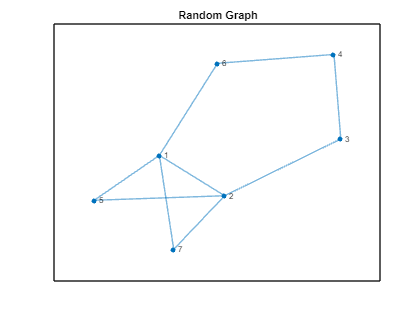


% Plot the graph
figure;
plot(G1);
title('Random Graph');


% Calcular el Laplaciano y la matriz de grado
D = diag(sum(A, 2));
L = D - A;

% Parámetro lambda
lambda = -1/n; % Ajusta según sea necesario

% Crear la matriz A usando la fórmula y Asegurar que W sea doblemente estocástica
W = eye(n) + lambda * L

W =     0.4286    0.1429         0         0    0.1429    0.1429    0.1429
    0.1429    0.4286    0.1429         0    0.1429         0    0.1429
         0    0.1429    0.7143    0.1429         0         0         0
         0         0    0.1429    0.7143         0    0.1429         0
    0.1429    0.1429         0         0    0.7143         0         0
    0.1429         0         0    0.1429         0    0.7143         0
    0.1429    0.1429         0         0         0         0    0.7143



G1=graph(W)

G1 =   graph with properties:

    Edges: [16×2 table]
    Nodes: [7×0 table]


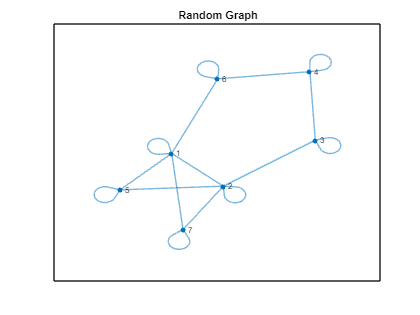


% Plot the graph
figure;
plot(G1);
title('Random Graph');

Se simula un protocolo de consenso en tiempo discreto para un sistema de 7 nodos, en donde se establece un estado inicial aleatorio para cada nodo dentro del intervalo [−5,5]. Luego, el sistema evoluciona durante 50 iteraciones, actualizando los estados de cada nodo mediante la fórmula x(k)=W⋅x(k−1), donde W es la matriz previamente calculada. Los estados de todos los nodos se almacenan en una matriz, mostrando cómo evolucionan los estados de los nodos hacia un acuerdo a lo largo del tiempo. Finalmente, se visualiza la evolución de los estados de los nodos con un gráfico, destacando el protocolo de consenso.

% Estado inicial aleatorio entre -5 y 5
x0 = (rand(n, 1) - 0.5) * 10; 

% Número de iteraciones
iterations = 50;

% Inicializar la matriz de estados
x = zeros(n, iterations);
x(:, 1) = x0;

% Proceso de consenso en tiempo discreto
for k = 2:iterations
    x(:, k) = W * x(:, k-1);
end
disp(x(iterations))

    0.6357



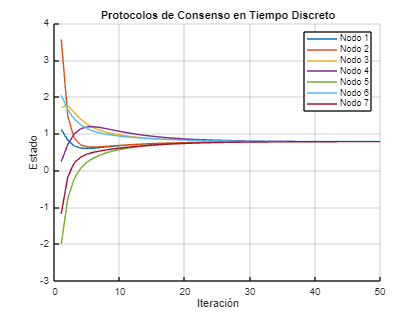

% Graficar los estados en cada iteración para todos los nodos
figure;
hold on;
for i = 1:n
    plot(1:iterations, x(i, :), 'DisplayName', ['Nodo ', num2str(i)]);
end
hold off;

title('Protocolos de Consenso en Tiempo Discreto');
xlabel('Iteración');
ylabel('Estado');
legend;
grid on;

## El protocolo de consenso en tiempo discreto para un Grafo dirigido con un nodo raiz

Se realiza un protocolo de consenso en un árbol dirigido con un nodo raíz aleatorio. Primero, selecciona un nodo raíz aleatorio y genera una permutación de los nodos para simular el crecimiento del árbol, asegurando que el primer nodo sea la raíz. Luego, conecta cada nodo con un nodo anterior en la lista para garantizar la conectividad del árbol, creando aristas dirigidas. La matriz de adyacencia A_root representa este árbol.

Finalmente, se simula el consenso en tiempo discreto con estados iniciales aleatorios, actualizando los estados de los nodos durante 50 iteraciones. Los resultados se visualizan en dos gráficos: uno que muestra el árbol dirigido y otro que muestra la evolución de los estados de los nodos a lo largo del tiempo.

% Seleccionar un nodo raíz aleatorio
root = randi([1 n]);
disp(['Nodo raíz: ', num2str(root)]);

Nodo raíz: 4



% Generar una permutación aleatoria de nodos (para simular crecimiento del árbol)
nodes = randperm(n);

% Asegurar que el primer nodo es la raíz
nodes(nodes == root) = [];
nodes = [root, nodes] ;

% Conectar cada nodo con un nodo previo de la lista para garantizar conectividad
for i = 2:n
    parent = nodes(randi(i-1)); % Elegir aleatoriamente un nodo anterior como padre
    A(parent, nodes(i)) = 1; % Crear arista dirigida
    A_root=A;
end

display(A_root)

A_root =      0     1     0     0     1     1     1
     1     0     1     0     1     0     1
     0     1     0     1     0     0     0
     0     0     1     0     1     1     1
     1     1     1     0     0     0     0
     1     1     0     1     0     0     0
     1     1     0     0     0     0     0



% Calcular el Laplaciano y la matriz de grado
D_root = diag(sum(A_root, 2));
L_root = D_root - A_root;

% Parámetro lambda
lambda_r = -1/n; % Ajusta según sea necesario

% Crear la matriz A usando la fórmula y Asegurar que W sea doblemente estocástica
W_root = eye(n) + lambda_r * L_root

W_root =     0.4286    0.1429         0         0    0.1429    0.1429    0.1429
    0.1429    0.4286    0.1429         0    0.1429         0    0.1429
         0    0.1429    0.7143    0.1429         0         0         0
         0         0    0.1429    0.4286    0.1429    0.1429    0.1429
    0.1429    0.1429    0.1429         0    0.5714         0         0
    0.1429    0.1429         0    0.1429         0    0.5714         0
    0.1429    0.1429         0         0         0         0    0.7143


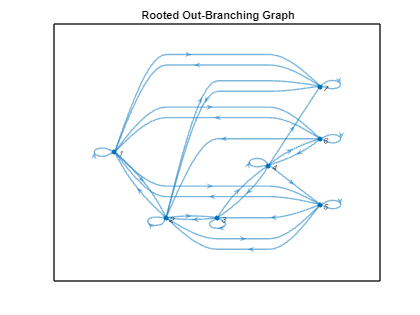


G = digraph(W_root);

% Graficar el árbol dirigido
figure;
plot(G, 'Layout', 'layered', 'Direction', 'right');
title('Rooted Out-Branching Graph');


% Estado inicial aleatorio entre -5 y 5
x0_2 = (rand(n, 1) - 0.5) * 10; 

% Número de iteraciones
iterations = 50;

% Inicializar la matriz de estados
x2 = zeros(n, iterations);
x2(:, 1) = x0_2;

% Proceso de consenso en tiempo discreto
for k = 2:iterations
    x2(:, k) = W_root * x2(:, k-1);
end
disp(x2(iterations))

   -0.2578



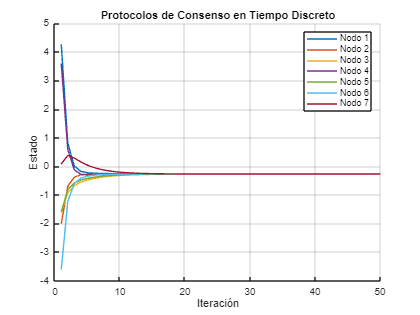

% Graficar los estados en cada iteración para todos los nodos
figure;
hold on;
for i = 1:n
    plot(1:iterations, x2(i, :), 'DisplayName', ['Nodo ', num2str(i)]);
end
hold off;

title('Protocolos de Consenso en Tiempo Discreto');
xlabel('Iteración');
ylabel('Estado');
legend;
grid on;

## Ecuación de consenso en grafos variantes en el tiempo

Se inicia con un **estado aleatorio** para cada nodo y, en cada iteración, se modifica aleatoriamente la estructura del grafo cambiando algunas conexiones con una probabilidad del 60%. Luego, se calcula la **matriz de consenso W(t)** a partir de la matriz de adyacencia modificada y la Laplaciana del grafo, asegurando que sea **doblemente estocástica**. Usando esta matriz, los estados de los nodos evolucionan conforme a la ecuación de consenso, con el objetivo de que todos los nodos alcancen un valor común a lo largo del tiempo. Finalmente, se **grafica la evolución** de cada nodo para analizar el proceso de consenso.

% Estado inicial aleatorio entre -5 y 5
x0_var = (rand(n, 1) - 0.5) * 10; 
x_var = zeros(n, iterations);
x_var(:,1) = x0_var;

% Simulación de la evolución temporal con matriz A(t)
for t = 2:iterations
    % Modificar aleatoriamente algunas conexiones en A(t) para simular variabilidad
    At = A_un;
    if rand < 0.5 % Probabilidad de cambio en la estructura
        i = randi(n);
        j = randi(n);
        if i ~= j
            At(i, j) = ~At(i, j);
            At(j, i) = At(i, j); % Mantener simetría
        end
    end
    % Calcular la matriz de consenso W(t)
    D_var = diag(sum(At, 2)); % Matriz de grado
    L_var = D_var - At; % Laplaciana
    lambda_var = -1/n; % Parámetro de ajuste
    Wt = eye(n) + lambda_var * L_var; % Matriz de pesos doblemente estocástica
    
    % Aplicar la ecuación de consenso
    x_var(:,t) = Wt * x_var(:,t-1);
end
disp(x_var(iterations))

    1.3367



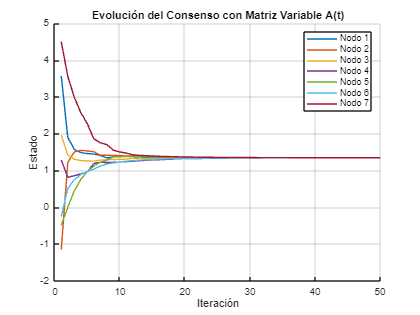

% Graficar la evolución del estado de los nodos
figure; hold on;
for i = 1:n
    plot(1:iterations, x_var(i, :), 'DisplayName', ['Nodo ', num2str(i)]);
end
hold off;
title('Evolución del Consenso con Matriz Variable A(t)');
xlabel('Iteración');
ylabel('Estado');
legend;
grid on;